# Introduction to Unsupervised Learning

**Unsupervised learning** refers to a machine learning algorithm that infers information from a given dataset without any guidance. The algorithm relies on underlying similarities and patterns within the data to learn how the variables are related to one another. So in a way, we're "letting the data speak for itself."

This is a great tool to use for initial exploration of a dataset without any defined hypothesis. Unsupervised learning is especially valuable in assessing a large dataset with multiple variables. 

## Defining Similarity

One of the most common ways to apply unsupervised learning is to assess the similarity within a dataset. Similarity can be quantitatively described using a **distance metric** between two variables. There are various types of distance metrics that can be used, but we'll just go over two of the most common ones: **Euclidean **and **correlation** distance.  

### Euclidean Distance

The **Euclidean distance** is broadly defined by the following formula: 


$$d\left(p,q\right)=\sqrt{\sum_{i=1}^n {\left(p_i -q_i \right)}^2 }$$


This is what the distance between p and q would look like on a 2D plane, where n = 2:

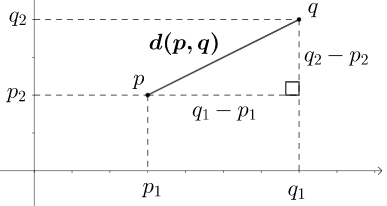

When analyzing biological data in MATLAB, we'll mostly be dealing with vectors instead of points. In these cases, we let n be equal to the length of the vectors we're comparing (note: the vectors must have the same length). 

For instance, let's say we're comparing vectors a and b as defined below: 

a = [1 2 3 4 5]
b = [25 16 9 4 1]

For this example, n = 5. We can calculate the Euclidean distance manually: 

d_man = sqrt(sum((a-b).^2))

We can also use the built-in function *pdist*:

d_fun = pdist([a;b],'euclidean')

Note that when using this function, we combined vectors a and b into a matrix. This is because the *pdist* function is used to calculate the distance between all vectors in a matrix. If we had a matrix with three vectors, we would be calculating the distance for three pairwise combinations (C(3,2) = 3):

c = [1 3 5 7 9]
d_3 = pdist([a;b;c])

Also note that Euclidean distance is the default metric for the *pdist* function.

### Correlation Distance

Another commonly used distance metric is **correlation**, and this is broadly defined as follows: 


$$d\left(p,q\right)=1-r$$


where r is the correlation coefficient. For Pearson's correlation:


$$r=\frac{\sum_{i=1}^n \left(p_i -\bar{p} \right)\left(q_i -\bar{q} \right)}{\sqrt{\sum_{i=1}^n {\left(p_i -\bar{p} \right)}^2 }\sqrt{\sum_{i=1}^n {\left(q_i -\bar{q} \right)}^2 }}$$
 

Going back to our example vectors a and b, the correlation distance can be calculated using the *pdist* function:

d_corr = pdist([a;b],'correlation')

We can also calculate the correlation distance using Spearman correlation:

d_spear = pdist([a;b],'spearman')

Note: refer to the *pdist* documentation for all available distance metrics.

# Clustering - Identifying distinct groups based on similarity

Now that we know how to quantitatively define similarity, we can use this information to cluster data. For this lesson, we'll be going over two types of clustering techniques: **hirarchical** and **k-means** clustering.

## Hierarchical Clustering

In **hierarchical clustering**, each observation starts in its own cluster at the base of the hierarchy. As we move up the hierarchy, observations that are most similar group together first until all observations are linked. This hierarchy of observations is often depicted as a **dendogram**, which is shown below: 

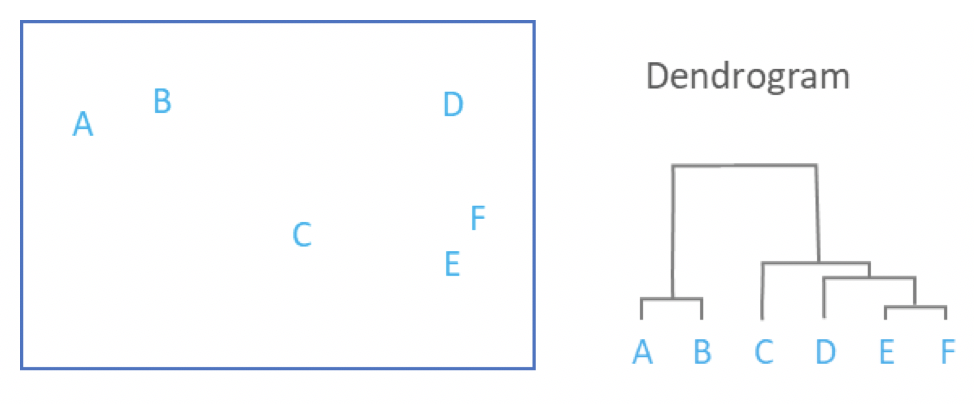

In MATLAB, we can perform hierarchical clustering of a dataset using the *clustergram* function. 

### Example: applying hierarchical clustering for the Framingham data

As you may recall, the Framingham data is a large dataset containing many biological measurements and logistical information of thousands of patients. Let's say we're interested in what the subset of cardiovascular-related measurements for a small set of patients can tell us using hierarchical clustering. 

The first step is to load the data and define the subset we're interested in:

fram = readtable('frmgham2.xls')
fram.Properties.VariableNames
cardio_vars = {'RANDID','TOTCHOL','SYSBP','DIABP','BMI',...
    'HEARTRTE','GLUCOSE','HDLC','LDLC'};
fram_cardio = fram(:,cardio_vars)

We'll remove rows containing NaN values and get the subset for the first 30 entries. We'll also create a variable for the patient IDs and an array variable for the cardiovascular-related measurements:

fram_cardio = rmmissing(fram_cardio)
fram_cardio = fram_cardio(1:30,:)
patient_ID = fram_cardio.RANDID
fram_cardio_data = table2array(fram_cardio(:,2:end))

Now we can perform hierarchical clustering for this data subset. For this example, we'll use Euclidean distance (default) as our distance metric for assessing similarity. We'll also cluster along both rows and columns (default):

fram_cardio_cg = clustergram(fram_cardio_data)

We can see that this clustergram is not very informative, as each column represents a different measurement with its own range of values. We can make our clustergram more informative by standardizing the values in each column. We'll also add the variable names for both rows and columns:

col_names = fram_cardio.Properties.VariableNames(2:end)
fram_cardio_cg_std = clustergram(fram_cardio_data,...
    'Standardize','column',...
    'RowLabels',patient_ID,...
    'ColumnLabels',col_names)

Now this is much more informative: we can see how specific measurements compare between patient clusters, and which patients are most similar. Let's see how the clustergram changes if we use Pearson's correlation as our distance metric:

fram_cardio_cg_corr = clustergram(fram_cardio_data,...
    'Standardize','column',...
    'RowLabels',patient_ID,...
    'ColumnLabels',col_names,...
    'RowPDist','correlation',...
    'ColumnPDist','correlation')

Question: How did the clustering change when using correlation as our distance metric? What information can you infer from the clustergram?

## K-means Clustering

For **k-means clustering**, we specify how many distinct groups we think that the data will cluster into. This is the opposite to what hierarchical clustering does. We can therefore regard hierarchical clustering as a "bottom-up" approach, whereas k-means clustering takes a "top-down" approach.

When applying k-means clustering, a **silhouette analysis** can be done to determine the optimal value for k (number of clusters). For this analysis, we calculate the silhouette value for each observation and assess how they compare within a cluster by generating a **silhouette plot**. The silhouette value measures how similar an observation is to its own cluster compared to others based on a distance metric. Below is an example of k-means clustering with its corresponding silhouette plot based on squared Euclidean distance (default): 

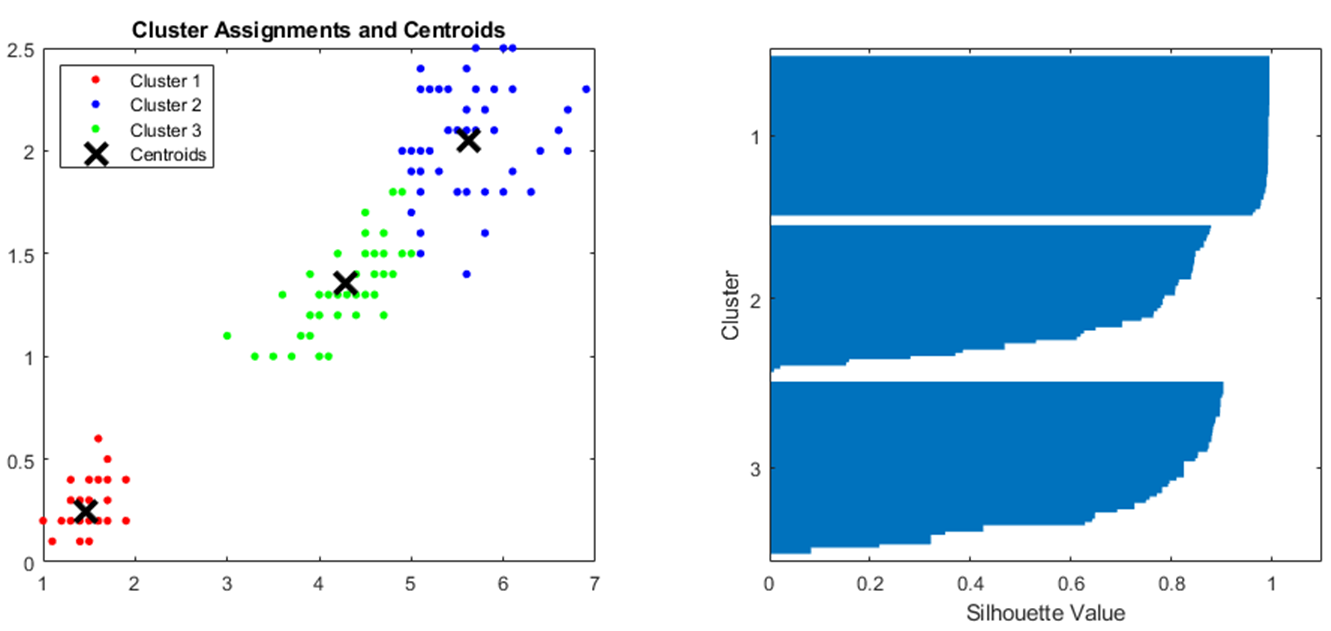

The silhouette value ranges from -1 to 1, where a higher positive value implies that an observation is well-matched to its cluster and vice-versa. One way to determine the optimal k value is to compare the mean of all silhouette values (**silhouette statistic**) for different values of k. For example, the plot below shows the silhouette statistic for k values ranging from 2 to 5 for the data previously shown: 

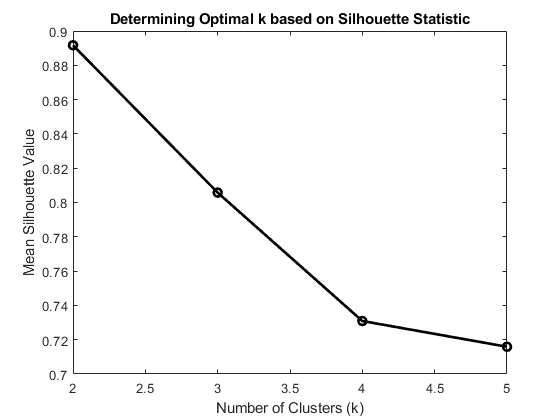

Based on this plot, we can see that k = 2 is the optimal option for clustering this data:

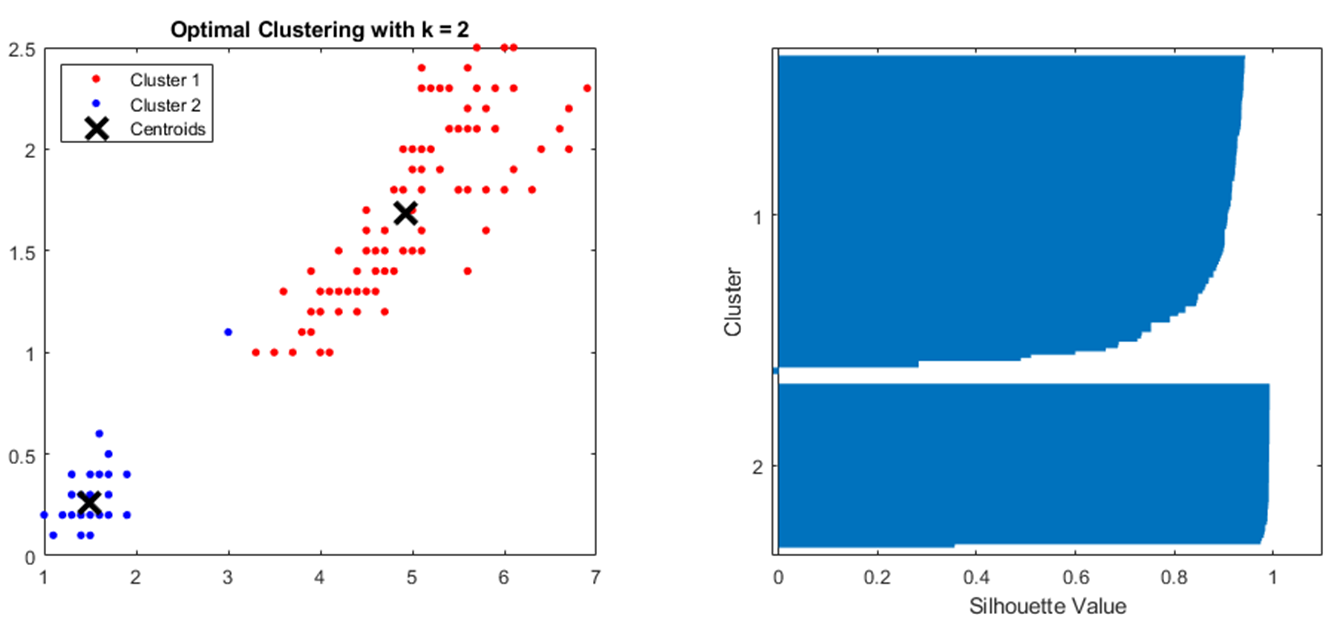

In MATLAB, we use the *kmeans* function to categorize our data into k clusters, where k is our predicted number of distinct groups. The *silhouette* function is used to calculate the silhouette value for each observation based on its cluster assignment. This function also generates a silhouette plot. 

### Example: applying k-means clustering for the Framingham data

To more easily visualize k-means clustering, we'll consider how diabetic patients cluster based on BMI and blood glucose level: 

fram_subset = fram((fram.DIABETES==1),{'BMI','GLUCOSE'})
fram_subset = rmmissing(fram_subset)
figure
plot(fram_subset.BMI,fram_subset.GLUCOSE,'ko')
xlabel('BMI'); ylabel('Blood Glucose')
title('BMI vs. Blood Glucose for Diabetic Patients')

Let's assess the silhouette statistic for k values ranging from 2 to 5: 

X = table2array(fram_subset)
k = 2:5; s = zeros(length(k),1);
for i = 1:length(k)
    idx = kmeans(X,k(i));
    s_values = silhouette(X,idx);
    s(i) = mean(s_values);
end
figure 
plot(k,s,'k-o','LineWidth',2)
xlabel('Number of Clusters (k)')
ylabel('Mean Silhouette Value')
title('Determining Optimal k based on Silhouette Statistic')

Based on this plot, we can see that the optimal number of clusters is 2. Let's visualize how the data separates based on k = 2 and assess the corresponding silhouette plot:

% Perform k-means clustering
k = 2
[idx,C] = kmeans(X,k)

% Define figure variables
figure
marker = {'r.','b.','g.','c.','m.'}
legend_lab = cell(k,1)

% Scatter plot with color-coded clustering
subplot(1,2,1)
for i = 1:k
    plot(X(idx==i,1),X(idx==i,2),marker{i},'MarkerSize',12)
    legend_lab(i) = {strcat("Cluster ",num2str(i))}
    hold on
end
plot(C(:,1),C(:,2),'kx''MarkerSize',15,'LineWidth',3) 
legend(vertcat(legend_lab,{'Centroids'}))
xlabel('BMI'); ylabel('Blood Glucose')
title(strcat("K-means Clustering with k = ",num2str(k)))
hold off
% Silhouette plot
subplot(1,2,2)
silhouette(X,idx)

Question: What information can you infer from the plot we generated? Is there anything concerning within our silhouette plot?

Activity: How can we modify the code above to apply k-means clustering based on correlation distance with k = 3?

# Dimensionality Reduction - Representing the variability in the dataset in lower dimensions

Biomedial data is often tremendously large and highly complex. Thus, it's hard to interpret this data when considering all the information available. By applying **dimensionality reduction**, we can transform the data into a lower-dimension representation that is much easier to interpret. In this lesson, we'll go over one type of dimensionality reduction method known as **principal component analysis**, or **PCA**. 

## Principal Component Analysis

In PCA, an orthogonal linear transformation is applied to the data, yielding a new coordinate system defined by principal components. A **principal component (PC) **is a linear combination of the **features**, or descriptive variables, in the dataset. The number of features in a dataset also dictates the number of PCs that are determined. 

The main goal when conducting PCA is to determine a ranked list of linearly independent principal components that altogether describe the variance within the data. This list of PCs is ranked by decreasing percentage of variance explained, where the first PC explains the most variance, or is most representative, of the data. The figure below shows an example of how much variance each PC explains for a dataset with 10 features: 

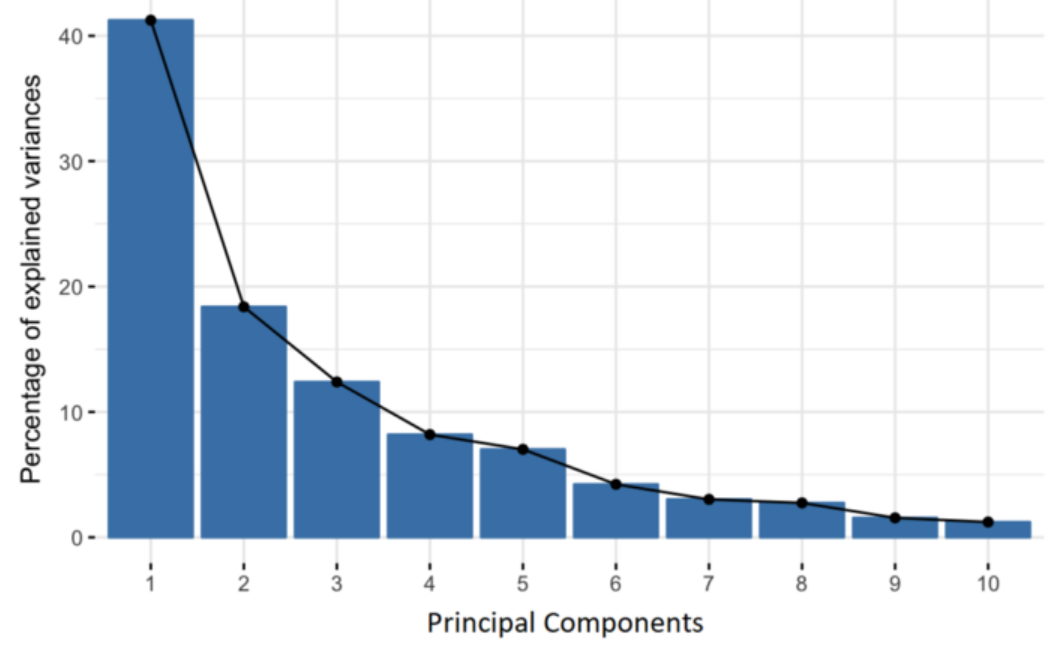

For the example shown above, we are able to represent ~60% of the variance using the first two PCs. In other words, if we were to plot the data based on PC1 and PC2, we would be visualizing a two-dimensional representation of the data that explains ~60% of the variance. 

PCA is typically done by (1) **eigenvalue decomposition (EVD)** of the data covariance matrix, or (2) **singular vector decomposition (SVD)** of the data. For this lesson, we'll not delve into the specifics of how EVD or SVD is applied, but for more information, refer to [this link](https://builtin.com/data-science/step-step-explanation-principal-component-analysis) for EVD and [this link](https://towardsdatascience.com/svd-8c2f72e264f) for SVD. 

In MATLAB, the *pca* function is used to perform PCA using the SVD algorithm.

### Example: applying PCA for the Framingham data

For this analysis, we'll consider a subset of the first 1000 entries containing all of the measured (not categorical) data: 

meas_vars = {'AGE','SYSBP','DIABP','CIGPDAY','TOTCHOL',...
    'HDLC','LDLC','BMI','GLUCOSE','HEARTRTE'};
fram_meas = fram(:,meas_vars)
fram_meas = rmmissing(fram_meas)
fram_meas = fram_meas(1:1000,:)
fram_meas_data = table2array(fram_meas)
size(fram_meas_data) % 1000 x 10 matrix

This data subset contains 10 features, or descriptive variables. This means that we'll be determining 10 linearly independent PCs by peforming PCA: 

[coeff,score,~,~,explained,~] = pca(fram_meas_data)

Here we defined three output variables: coeff, score, and explained. Coeff is a 10 x 10 matrix, where each column vector lists the coefficient values for a PC. Score is a 1000 x 10 matrix of transformed observations, or the principal component scores. Explained is a vector of length 10 that lists the percentage of variance explained by each PC in ranked order. Let's visualize the 2D representation of this data by plotting the scores for PC1 and PC2: 

scatter(score(:,1),score(:,2))
xlabel('PC1'); ylabel('PC2')
title('PCA of Frammingham Data')

Question: What do the first two PCs mean? What percentage of variance do they explain?

# Unsupervised vs. Supervised Learning

All of the methods discussed thus far serve as applications for unsupervised learning. In machine learning, we can also analyze data using **supervised learning**, where we have information (e.g. labels) on the output data. Supervised learning is typically used to train and develop predictive or classification tools based on labeled data. 

We can also apply supervised learning for certain unsupervised methods. For example, we can visualize our previous 2D PCA plot with data points labeled according to the diabetes status of the patient: 

% Define data
vars = {'DIABETES','AGE','SYSBP','DIABP','CIGPDAY','TOTCHOL',...
    'HDLC','LDLC','BMI','GLUCOSE','HEARTRTE'};
fram_lab = fram(:,vars)
fram_lab = rmmissing(fram_lab)
fram_lab = fram_lab(1:1000,:)
diab = fram_lab.DIABETES
fram_lab_data = table2array(fram_lab(:,2:end))

% Perform PCA
[coeff,score,~,~,explained,~] = pca(fram_lab_data)

% Genera PCA plot with labeled points
plot(score(diab==0,1),score(diab==0,2),'b.','MarkerSize',12)
hold on
plot(score(diab==1,1),score(diab==1,2),'r.','MarkerSize',12)
xlabel('PC1'); ylabel('PC2')
legend('Not diabetic','Diabetic')
title('PCA of Frammingham Data')

This supervised version of PCA is often used to assess whether a dataset can be classified into distinct groups based on lower-dimension representations. 

# Summary

- Unsupervised learning allows us to infer information about a dataset without any user guidance based on underlying similarities and patterns

- Common applications of unsupervised learning to analyze biomedical data include clustering (hierarchical, k-means) and dimensionality reduction (principal component analysis)

- Hierarchical clustering involves a "bottom-up" approach, whereas k-means clustering applies a "top-down" approach, to assign data into groups

- Principal component analysis allows us to transform highly complex data into lower-dimension representations that are easier to interpret

- In contrast to unsupervised learning, supervised learning includes information on the output variables (e.g. labels) that can be used to train and develop predictive or classification tools 

### Built-in MATLAB functions covered in this lesson:

- *pdist:* quantifies similarity using a distance metric (e.g. euclidean, correlation)

- *clustergram:* performs hierarchical clustering

- *kmeans:* performs k-means clustering

- *silhouette:* calculates silhouette values and generates a silhouette plot based on k-means clustering of a dataset

- *pca:* performs principal component analysis (PCA)

### References for Additional Information:

- [Eigenvalue Decomposition (EVD)](https://builtin.com/data-science/step-step-explanation-principal-component-analysis)

- [Singular Vector Decomposition (SVD)](https://towardsdatascience.com/svd-8c2f72e264f)